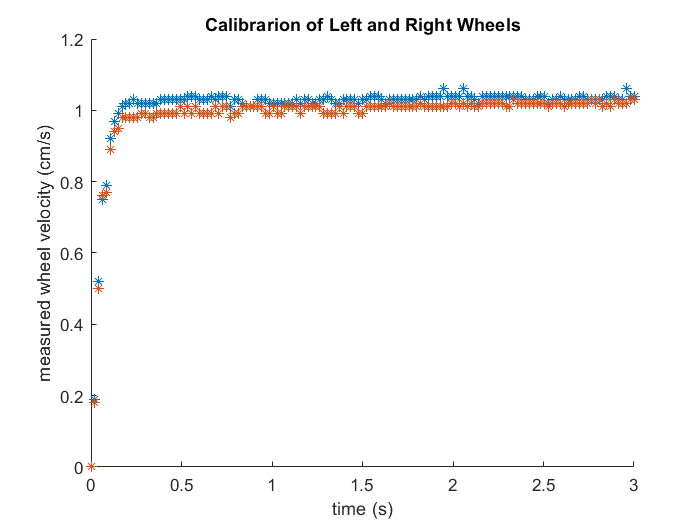

%clear;

%wheel_calibration_data = readmatrix("new_wheel_calibration.csv")
frequency_calibration_data = readmatrix("new_gyro_calibration.csv");


time = linspace(0, 3, 141);
l_wheel = wheelcalibration3(:,1);
r_wheel = wheelcalibration3(:,2);

clf; hold on;
plot(time, l_wheel, "*");
plot(time, r_wheel, "*");

title("Calibrarion of Left and Right Wheels");
xlabel("time (s)"); ylabel("measured wheel velocity (cm/s)");

Plotting Curve Fitting Data:

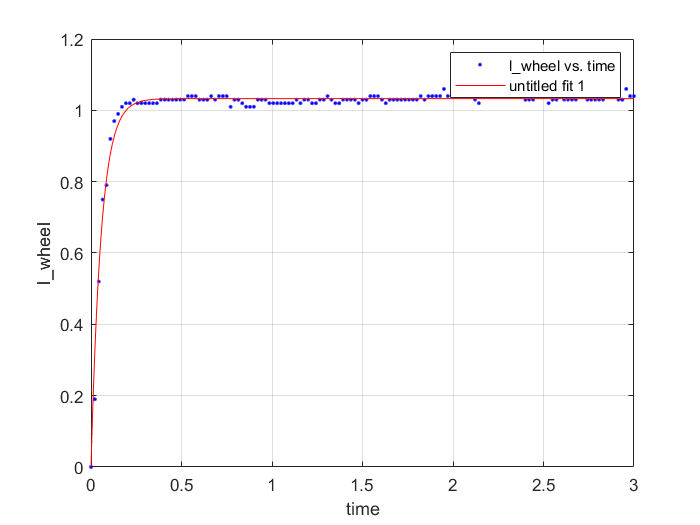

ans =      General model:
     ans(x) = a*(1-exp(-(1/T)*x))
     Coefficients (with 95% confidence bounds):
       T =     0.05643  (0.05418, 0.05869)
       a =       1.033  (1.03, 1.036)

createLWheelFit(time, l_wheel)

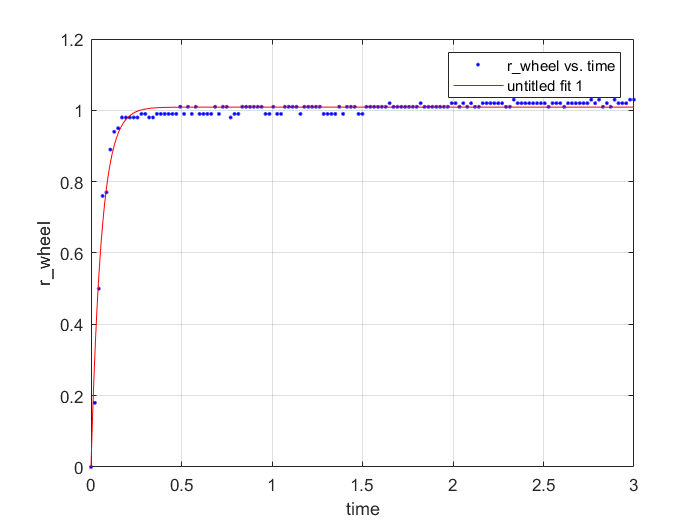

ans =      General model:
     ans(x) = a*(1-exp(-(1/T)*x))
     Coefficients (with 95% confidence bounds):
       T =     0.05724  (0.05462, 0.05987)
       a =       1.009  (1.006, 1.012)

createRWheelFit(time, r_wheel)

Frequency Calibration:

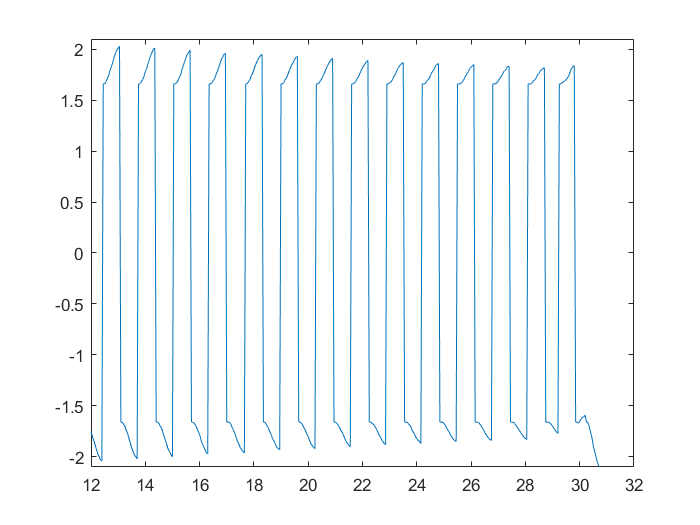

clf;
time = 0.05*[1:length(frequency_calibration_data)];
plot(time, frequency_calibration_data);
xlim([12, 32]); ylim([-2.1, 2.1]);


Wn_cycles = (25.45 - 12.4)/20;
Wn = 2*pi*Wn_cycles;            % radians per second
L_eff = 9.81/(Wn^2);

Functions for Making Curve Fit Plots

function [fitresult, gof] = createLWheelFit(time, l_wheel)
%CREATEFIT(TIME,L_WHEEL)
%  Create a fit.
%
%  Data for 'untitled fit 1' fit:
%      X Input : time
%      Y Output: l_wheel
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 27-Feb-2023 11:34:30


%% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( time, l_wheel );

% Set up fittype and options.
ft = fittype( 'a*(1-exp(-(1/T)*x))', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.278498218867048 0.128610587325334];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );
legend( h, 'l_wheel vs. time', 'untitled fit 1', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'time', 'Interpreter', 'none' );
ylabel( 'l_wheel', 'Interpreter', 'none' );
grid on

end

function [fitresult, gof] = createRWheelFit(time, r_wheel)
%CREATEFIT(TIME,R_WHEEL)
%  Create a fit.
%
%  Data for 'untitled fit 1' fit:
%      X Input : time
%      Y Output: r_wheel
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 27-Feb-2023 11:37:35


%% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( time, r_wheel );

% Set up fittype and options.
ft = fittype( 'a*(1-exp(-(1/T)*x))', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.546881519204984 0.957506835434298];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );
legend( h, 'r_wheel vs. time', 'untitled fit 1', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'time', 'Interpreter', 'none' );
ylabel( 'r_wheel', 'Interpreter', 'none' );
grid on

end